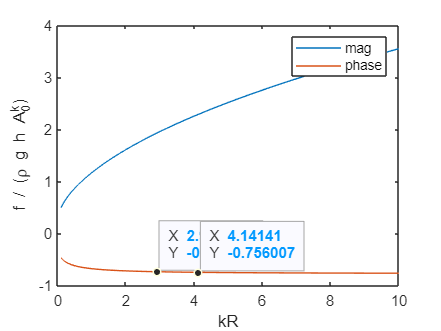

% equation 156 of Olaya paper
% https://ieeexplore.ieee.org/document/6895317/
% excitation force with heave plate
% including excitation phase

kh = 10;
kR = linspace(0,10);

N0 = 1/2 * (1 + sinh(2*kh)/(2*kh));
f_over_rho_g_h_A0k_exp_minus_kR = -4 * 1i * sqrt(N0) ./ ( cosh(kh) * besselh(0,1,kR,1) );

figure
plot(kR,abs(f_over_rho_g_h_A0k_exp_minus_kR),kR,angle(f_over_rho_g_h_A0k_exp_minus_kR))
legend('mag','phase')
xlabel('kR')
ylabel('f / (\rho g h A_0^k)')

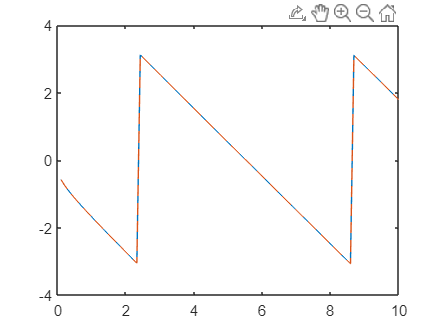

phase = angle( -1i * besselh(0, 2, kR) );
phase2 = wrapToPi(-pi/2 - angle( besselh(0, 1, kR) ));
figure
plot(kR,phase, kR,phase2,'--')